# Test Run

The program is designed as a callable function

## Test Paths

#### Each of the four paths available to test.  Press `Run Section` to run a test.

* Variable details are in the ***runSolver*** section of the ReadMe

* Independant sources can always be functions of time.  Even if they are constant, the simulation will run for the requested duration with the requested timestep.

* I know I started using _1 for path 0, this was a mistake, just look at the path number and know the indicator is 1 above the path number.  This file is not large enough for this to become confusing.

clc
clear

#### Path 0

G x(t) = B(t).  Circuit contains no non-linear or energy storage components

% Components
g1 = 5;
g2 = 3;
VSource_1 = @(t) sin(t);

% Solver Parameters
G_1 = [g1,-g1,1;-g1,g1+g2,0;1,0,0]

G_1 =      5    -5     1
    -5     8     0
     1     0     0


dGxdp_1 = {[1;-1;0],[1,2];[0;1;0],[2,0]}

dGxdp_1 = 2×2 cell array
    {3×1 double}    {[1 2]}
    {3×1 double}    {[2 0]}


B_1 = {[0;0;1], VSource_1, 1} %variable source

B_1 = 1×3 cell array
    {3×1 double}    {@(t)sin(t)}    {[1]}


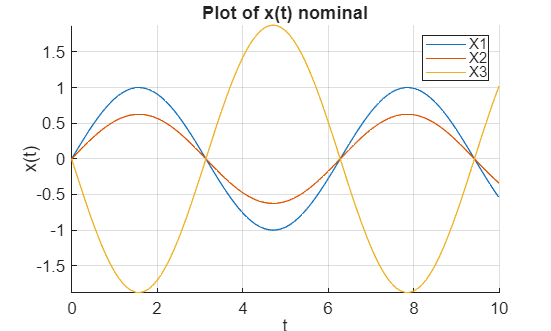

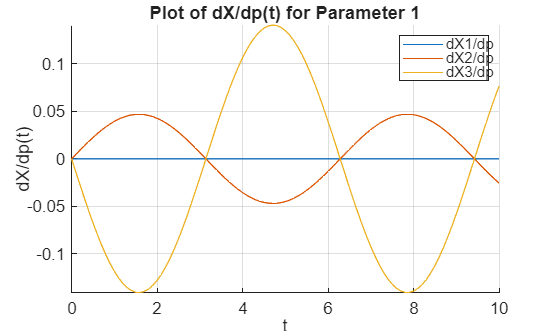

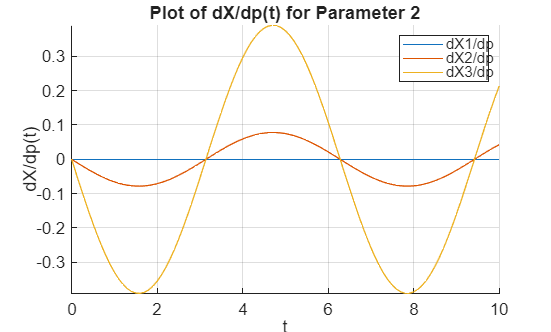

%B_1 = {[0;0;1], 6, 0} %constant source
lnth_1 = [3,2];
h_1 = 0.1;
time_1 = 10;

% Path (keep at 0)
path_1 = 0;

% Run
[xNomPlot_1,MPlot_1] = runSolver(0, 0, G_1, dGxdp_1, 0, 0, B_1, lnth_1, h_1, time_1, path_1);

xNomPlot_1

xNomPlot_1 =   Figure (1) with properties:

      Number: 1
        Name: ''
       Color: [1 1 1]
    Position: [290 182 560 337.1728]
       Units: 'pixels'

  Show all properties


MPlot_1

MPlot_1 =      2     3


#### Testing

Tested with above circuit with the constant and variable B(t)

- x(t) correct

- M(t) unchecked but not obviously wrong

clc
clear

#### Path 1

G x(t) + F(x(t)) = B(t).  Circuit contains nonlinear components, and does not contain energy storage components.

% Components
nonLinR_I = @(vH,vL) (vH-vL).^2;
nonLinR_dIdx = @(vH,vL) 2.*(vH-vL);
VSource_2 = @(t) sin(t);
g=5;

% Solver Parameters
G_2 = [0,0,1;0,g,0;1,0,0]

G_2 =      0     0     1
     0     5     0
     1     0     0


dGxdp_2 = {[0;1;0],[2,0]}

dGxdp_2 = 1×2 cell array
    {3×1 double}    {[2 0]}


F_2 = {[1;-1;0],nonLinR_I,[1,2]}

F_2 = 1×3 cell array
    {3×1 double}    {@(vH,vL)(vH-vL).^2}    {[1 2]}


dFdx_2 = {[1,-1,0;-1,1,0;0,0,0],nonLinR_dIdx,[1,2]}

dFdx_2 = 1×3 cell array
    {3×3 double}    {@(vH,vL)2.*(vH-vL)}    {[1 2]}


B_2 = {[0;0;1], VSource_2, 1} %variable source

B_2 = 1×3 cell array
    {3×1 double}    {@(t)sin(t)}    {[1]}


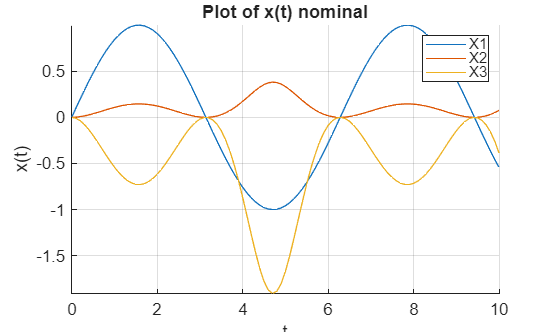

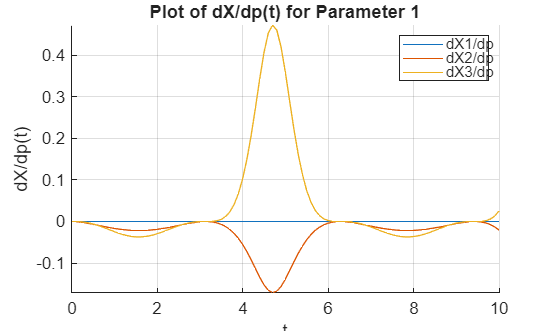

%B_2 = {[0;0;1], 6, 0} %constant source
lnth_2 = [3,1];
h_2 = 0.1;
time_2 = 10;

% Path (keep at 1)
path_2 = 1;

% Run
[xNomPlot_2, MPlot_2] = runSolver(0, 0, G_2, dGxdp_2, F_2, dFdx_2, B_2, lnth_2, h_2, time_2, path_2);

xNomPlot_2

xNomPlot_2 =   Figure (4) with properties:

      Number: 4
        Name: ''
       Color: [1 1 1]
    Position: [290 182 560 337.1728]
       Units: 'pixels'

  Show all properties


MPlot_2

MPlot_2 = 5

#### Testing

Tested with above circuit with the constant and variable B(t)

- x(t) at constant B is correct, x(t) at sinusodal unchecked but looks as expected

- M(t) unchecked but not obviously wrong

clc
clear

#### Path 2

C dx(t)/dt + G x(t) = B(t).  Circuit contains energy storage components, and does not contain nonlinear components.

% Components
VSource_3 = @(t) sin(t);
g=5;
c=3

c = 3


% Solver Parameters
G_3 = [0,0,1;0,g,0;1,0,0]

G_3 =      0     0     1
     0     5     0
     1     0     0


dGxdp_3 = {[0;1;0],[2,0];[0;0;0],[0,0]}

dGxdp_3 = 2×2 cell array
    {3×1 double}    {[2 0]}
    {3×1 double}    {[0 0]}


C_3 = [c,-c,0;-c,c,0;0,0,0]

C_3 =      3    -3     0
    -3     3     0
     0     0     0


dCxdp_3 = {[0;0;0],[0,0];[1;-1;0],[1,2]}

dCxdp_3 = 2×2 cell array
    {3×1 double}    {[0 0]}
    {3×1 double}    {[1 2]}


%B_3 = {[0;0;1], VSource_3, 1} %variable source
B_3 = {[0;0;1], 6, 0} %constant source

B_3 = 1×3 cell array
    {3×1 double}    {[6]}    {[0]}


         0    6.0000    6.0000    6.0000    6.0000    6.0000    6.0000    6.0000    6.0000    6.0000    6.0000    6.0000    6.0000    6.0000    6.0000    6.0000    6.0000    6.0000    6.0000    6.0000    6.0000    6.0000    6.0000    6.0000    6.0000    6.0000    6.0000    6.0000    6.0000    6.0000    6.0000    6.0000    6.0000    6.0000    6.0000    6.0000    6.0000    6.0000    6.0000    6.0000    6.0000    6.0000    6.0000    6.0000    6.0000    6.0000    6.0000    6.0000    6.0000    6.0000    6.0000    6.0000    6.0000    6.0000    6.0000    6.0000    6.0000    6.0000    6.0000    6.0000    6.0000    6.0000    6.0000    6.0000    6.0000    6.0000    6.0000    6.0000    6.0000    6.0000    6.0000    6.0000    6.0000    6.0000    6.0000    6.0000    6.0000    6.0000    6.0000    6.0000    6.0000    6.0000    6.0000    6.0000    6.0000    6.0000    6.0000    6.0000    6.0000    6.0000    6.0000    6.0000    6.0000    6.0000    6.0000    6.0000    6.0000    6.0000    6.0000    6.0000

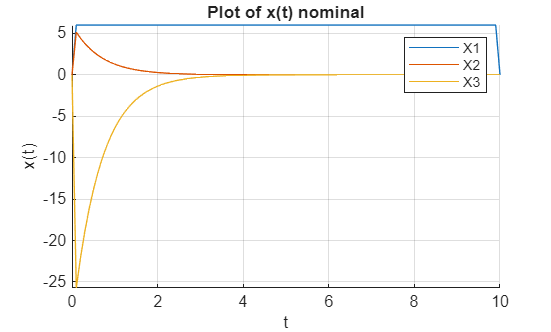

lnth_3 = [3,2];
h_3 = 0.1;
time_3 = 10;

% Path (keep at 2)
path_3 = 2;

% Run
[xNomPlot_3, MPlot_3] = runSolver(C_3, dCxdp_3, G_3, dGxdp_3, 0, 0, B_3, lnth_3, h_3, time_3, path_3);

xNomPlot_3

xNomPlot_3 =   Figure (6) with properties:

      Number: 6
        Name: ''
       Color: [1 1 1]
    Position: [290 182 560 337.1728]
       Units: 'pixels'

  Show all properties


MPlot_3

MPlot_3 =      7     8


#### Testing

Tested with above circuit with the constant and variable B(t)

- x(t) gets the shape expected, phase shift with the sinusodal Vin and transiant response settling at 0 with the constant Vin.  Constant works.

- M looks reasonable but not tested

clc
clear

#### Path 3

C dx(t)/dt + G x(t) + F(x(t)) = B(t).  Circuit contains both energy storage components and  nonlinear components.

% Components
VSource_4 = @(t) sin(t);
nonLinR_I = @(vH,vL) (vH-vL).^2;
nonLinR_dIdx = @(vH,vL) 2.*(vH-vL);
g=5;
c=3

c = 3


C_4 = [0,0,0;0,c,0;0,0,0]

C_4 =      0     0     0
     0     3     0
     0     0     0


dCxdp_4 = {[0;0;0],[0,0]; [0;1;0],[2,0]}

dCxdp_4 = 2×2 cell array
    {3×1 double}    {[0 0]}
    {3×1 double}    {[2 0]}


G_4 = [g,-g,1;-g,g,0;1,0,0]

G_4 =      5    -5     1
    -5     5     0
     1     0     0


dGxdp_4 = {[1;-1;0],[1,2];[0;0;0],[0,0]}

dGxdp_4 = 2×2 cell array
    {3×1 double}    {[1 2]}
    {3×1 double}    {[0 0]}


F_4 = {[0;1;0], nonLinR_I,[2,0]}

F_4 = 1×3 cell array
    {3×1 double}    {@(vH,vL)(vH-vL).^2}    {[2 0]}


dFdx_4 = {[0,0,0;0,1,0;0,0,0], nonLinR_dIdx,[2,0]}

dFdx_4 = 1×3 cell array
    {3×3 double}    {@(vH,vL)2.*(vH-vL)}    {[2 0]}


%B_4 = {[0;0;1], VSource_4, 1} %variable source
B_4 = {[0;0;1], 6, 0} %constant source

B_4 = 1×3 cell array
    {3×1 double}    {[6]}    {[0]}


         0    6.0000    6.0000    6.0000    6.0000    6.0000    6.0000    6.0000    6.0000    6.0000    6.0000    6.0000    6.0000    6.0000    6.0000    6.0000    6.0000    6.0000    6.0000    6.0000    6.0000    6.0000    6.0000    6.0000    6.0000    6.0000    6.0000    6.0000    6.0000    6.0000    6.0000    6.0000    6.0000    6.0000    6.0000    6.0000    6.0000    6.0000    6.0000    6.0000    6.0000    6.0000    6.0000    6.0000    6.0000    6.0000    6.0000    6.0000    6.0000    6.0000    6.0000    6.0000    6.0000    6.0000    6.0000    6.0000    6.0000    6.0000    6.0000    6.0000    6.0000    6.0000    6.0000    6.0000    6.0000    6.0000    6.0000    6.0000    6.0000    6.0000    6.0000    6.0000    6.0000    6.0000    6.0000    6.0000    6.0000    6.0000    6.0000    6.0000    6.0000    6.0000    6.0000    6.0000    6.0000    6.0000    6.0000    6.0000    6.0000    6.0000    6.0000    6.0000    6.0000    6.0000    6.0000    6.0000    6.0000    6.0000    6.0000    6.0000

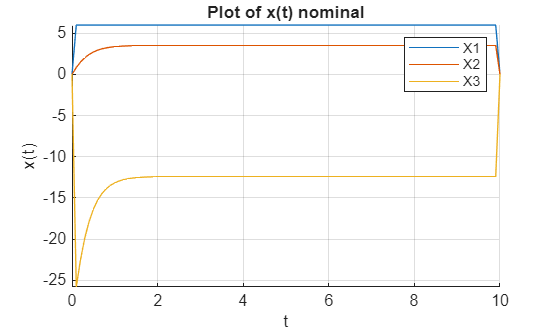

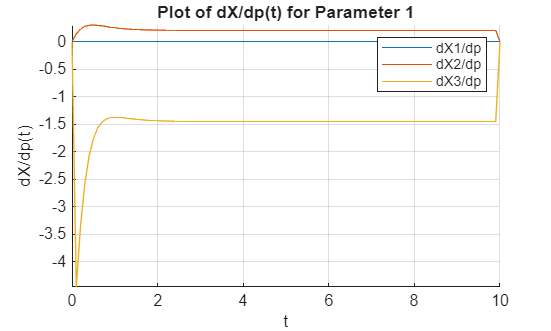

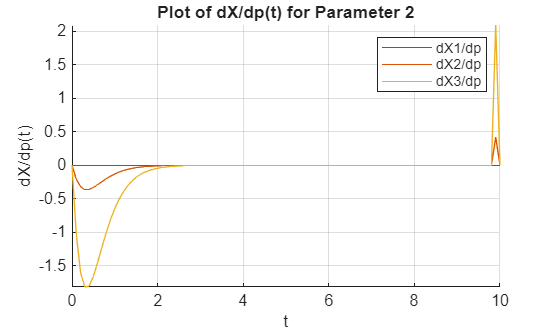

lnth_4 = [3,2];
h_4 = 0.1;
time_4 = 10;

% Path (keep at 3)
path_4 = 3;

% Run
[xNomPlot_4, MPlot_4,x] = runSolver(C_4, dCxdp_4, G_4, dGxdp_4, F_4, dFdx_4, B_4, lnth_4, h_4, time_4, path_4);

xNomPlot_4

xNomPlot_4 =   Figure (9) with properties:

      Number: 9
        Name: ''
       Color: [1 1 1]
    Position: [290 182 560 337.1728]
       Units: 'pixels'

  Show all properties


MPlot_4

MPlot_4 =     10    11


x

x =          0    6.0000    6.0000    6.0000    6.0000    6.0000    6.0000    6.0000    6.0000    6.0000    6.0000    6.0000    6.0000    6.0000    6.0000    6.0000    6.0000    6.0000    6.0000    6.0000    6.0000    6.0000    6.0000    6.0000    6.0000    6.0000    6.0000    6.0000    6.0000    6.0000    6.0000    6.0000    6.0000    6.0000    6.0000    6.0000    6.0000    6.0000    6.0000    6.0000    6.0000    6.0000    6.0000    6.0000    6.0000    6.0000    6.0000    6.0000    6.0000    6.0000
         0    0.8371    1.5096    2.0330    2.4309    2.7281    2.9473    3.1075    3.2238    3.3078    3.3682    3.4117    3.4428    3.4650    3.4810    3.4924    3.5005    3.5063    3.5105    3.5134    3.5155    3.5170    3.5181    3.5189    3.5194    3.5198    3.5201    3.5203    3.5204    3.5205    3.5206    3.5207    3.5207    3.5207    3.5208    3.5208    3.5208    3.5208    3.5208    3.5208    3.5208    3.5208    3.5208    3.5208    3.5208    3.5208    3.5208    3.5208    3.5208    3

#### Testing

Tested with above circuit with the constant and variable B(t)

- B(t) constant: transient response from the capacitor is present, I matches the value of V1, but V1 should be at 1 and I at -25.  **WRONG**, but I have no idea where it uses the same equasions as ones that turn out right.  Also, if V1 was right then the current would match and also be right, so its not fully broken.

- M looks reasonable but not tested